# Лабораторная работа №1

## студента: Красницького Микити

## Варіант - 9

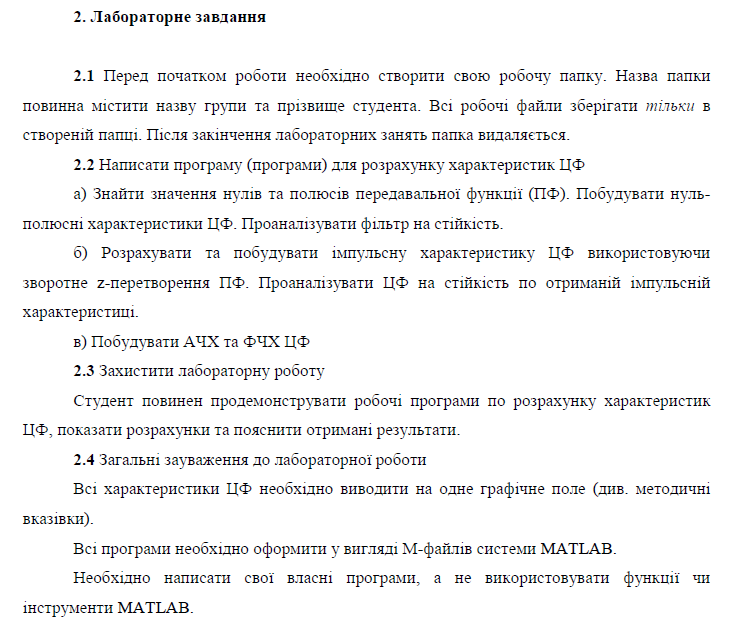

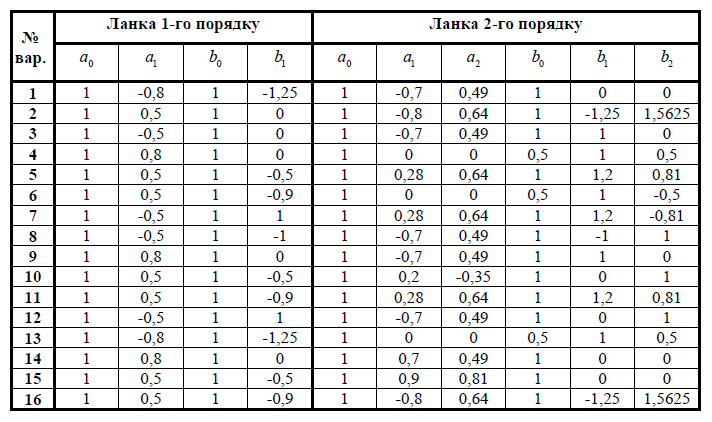

## 2.2 Розрахунок характеристик ЦФ 1го порядку

Умови за варіантом

close all;
clear all;

a0 = 1;
a1 = -0.8;
b0 = 1;
b1 = -1.25;

Частота - дискретная велечина. Пременная z зависит от нее. Нахожу нули и полюсі и изображаю их на комплексной плоскости.

w = 0:pi/100:2*pi;
z = exp(1i.*w);

Y = (b0-b1*z.^(-1));
X = (a0+a1*z.^(-1));

## Нулі та Полюси

syms x
nul = solve(b0 + b1*x^-1 == 0, x); %Nuli   (Ci)
pol = solve(a0 + a1*x^-1 == 0, x); %Polysi (Pk)
subplot(2,2,1);
zplane(nul,pol);

Полюсы должны находиться в пределе единичного круга для удовлетворения условиям стабильости цифровой системы. Как видно из графа справа, крести - полюс, - находится в единичном круге с чего заключаю, что система устойчивая.

## АЧХ

H = (b0-b1*z.^(-1))./(a0+a1*z.^(-1));
% H = Y./X; 
subplot(2,2,2);
plot(w,abs(H));
grid on;
title('ACH');

## ИХ

syms n;
f = (b0 + b1*n^-1)/(a0 + a1*n^-1);
F = iztrans(f);

t = 0:0.25:10;
F = -((4/5).^t)*9/16;%% Function that returns from iztrans
F(1) = 25/16;        %% Take into account Delta-Kroncer Function
subplot(2,2,3);
stem(t, F)

% Check of impulse characteristic
%[h, n] = impz([b0 b1], [a0 a1])
%stem(n, h)

## ФЧХ

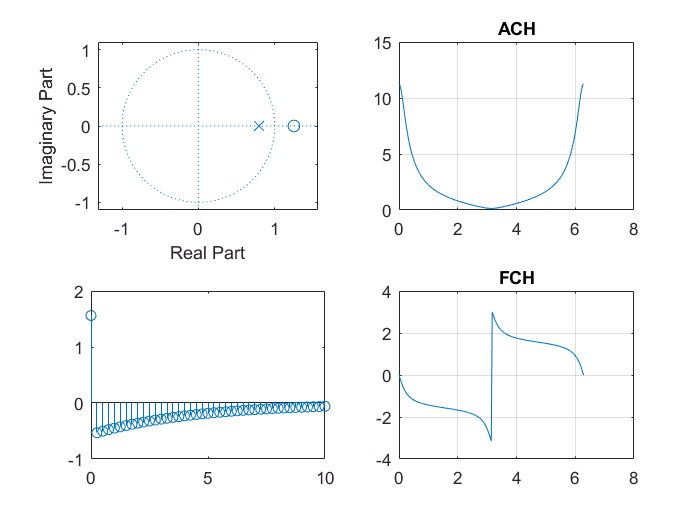

subplot(2,2,4);
plot(w,angle(H));
grid on;
title('FCH');

## 2.3 Розрахунок характеристик ЦФ 2го порядку

Умови за варіантом

close all;
clear all;

a0 = 1;
a1 = -0.7;
a2 = 0.49;
b0 = 1;
b1 = 1;
b2 = 0.0002;

Частота - дискретная велечина. Пременная z зависит от нее. Нахожу нули и полюсі и изображаю их на комплексной плоскости.

w = 0:pi/100:4*pi;
z = exp(1i.*w);

Y = b0 + b1*z.^(-1) + b2*z.^(-2);
X = a0 + a1*z.^(-1) + a2*z.^(-2);

## Нулі та Полюси

syms x
nul = solve(b0 + b1*x^-1 + b2*x^-2 == 0, x); %Nuli   (Ci) 
pol = solve(a0 + a1*x^-1 + a2*x^-2 == 0, x); %Polysi (Pk)
subplot(2,2,1);
zplane(nul,pol);

Цифровая система устойчива поскольку оба полюса лежат в единином круге на комплексной плоскости

## АЧХ

H = (b0 + b1*z.^(-1) + b2*z.^(-2))./(a0 + a1*z.^(-1) + a2*z.^(-2));
% H = Y./X; 
subplot(2,2,2);
plot(w,abs(H));
grid on;
title('ACH');

## ИХ

A = [1 -0.7 0.49];
B = [1 1 0];
[h,t] = impz(B,A);
subplot(2,2,3);
stem(t, h)

## ФЧХ

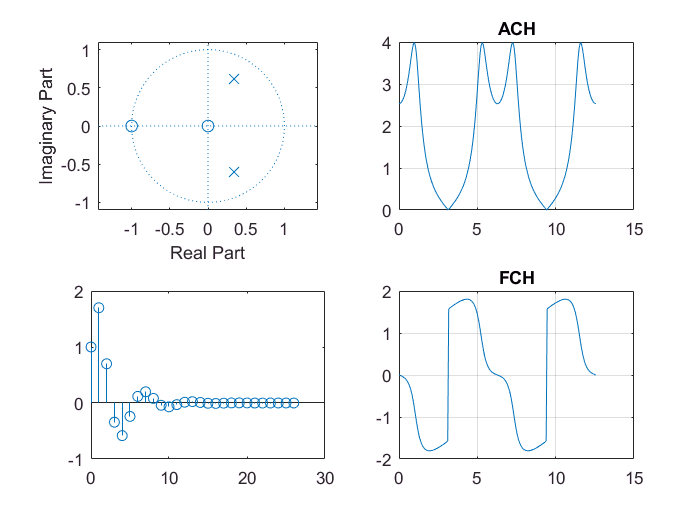

subplot(2,2,4);
plot(w,angle(H));
grid on;
title('FCH');